# File Transfer Progress Dialog Demo

This script demonstrates the two dialog-based progress displays:

- A standard MATLAB waitbar.

- A uiprogressdlg parented to a uifigure.

demoUrl = 'https://allen-brain-observatory.s3.us-west-2.amazonaws.com/visual-coding-2p/cell_specimens.json';
tempDownloadedFile = [tempname, '.json'];
fileCleanupObj = onCleanup(@() deleteIfExists(tempDownloadedFile));

## Standard Waitbar

Without a Figure argument, downloadFile uses a standard waitbar dialog.

downloadFile(tempDownloadedFile, demoUrl, ...
    DisplayMode="Dialog Box", ...
    UpdateInterval=1, ...
    ShowFilename=true);

## Progress Dialog In A UIFigure

Passing a uifigure through the Figure argument makes downloadFile use a uiprogressdlg instead of a standard waitbar.

fig = uifigure( ...
    'Name', 'File Transfer Progress Demo');
figureCleanupObj = onCleanup(@() deleteFigureIfExists(fig));

uilabel(fig, ...
    'Text', 'Progress is shown with uiprogressdlg attached to this uifigure.', ...
    'HorizontalAlignment', 'center', ...
    'VerticalAlignment', 'center', ...
    'Position', [1,1,fig.Position(3:4)]);
drawnow

downloadFile(tempDownloadedFile, demoUrl, ...
    DisplayMode="Dialog Box", ...
    UpdateInterval=1, ...
    ShowFilename=true, ...
    Figure=fig);
clear figureCleanupObj

## Local Functions

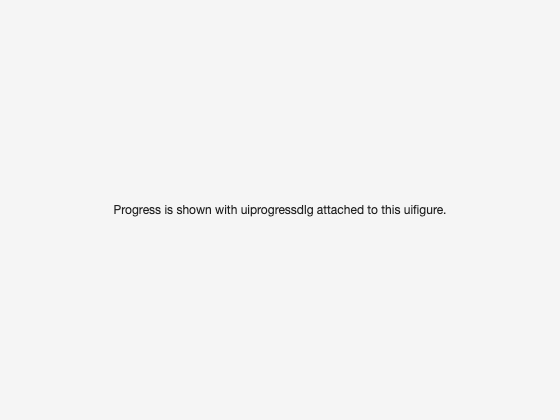

function deleteIfExists(filename)

    if isfile(filename)
        delete(filename)
    end
end
function deleteFigureIfExists(figureHandle)
    if isvalid(figureHandle)
        delete(figureHandle)
    end
end